format long e

% Linearly seperable differential equation to test rk4 implementation
df = @(t, w) (exp(t)-w)/t;

% IVP
a = 1;
alpha = 2;
N = 200;
h = 0.1;

% Exact solution to above
f = @(t) t.^-1.*exp(t)+(2-exp(1))*t.^-1;

% Calculate rk4 approximation
[ti, rk4_wi] = rk4(N, h, a, alpha, df);

% Calculate exact values
exact_wi = f(ti);

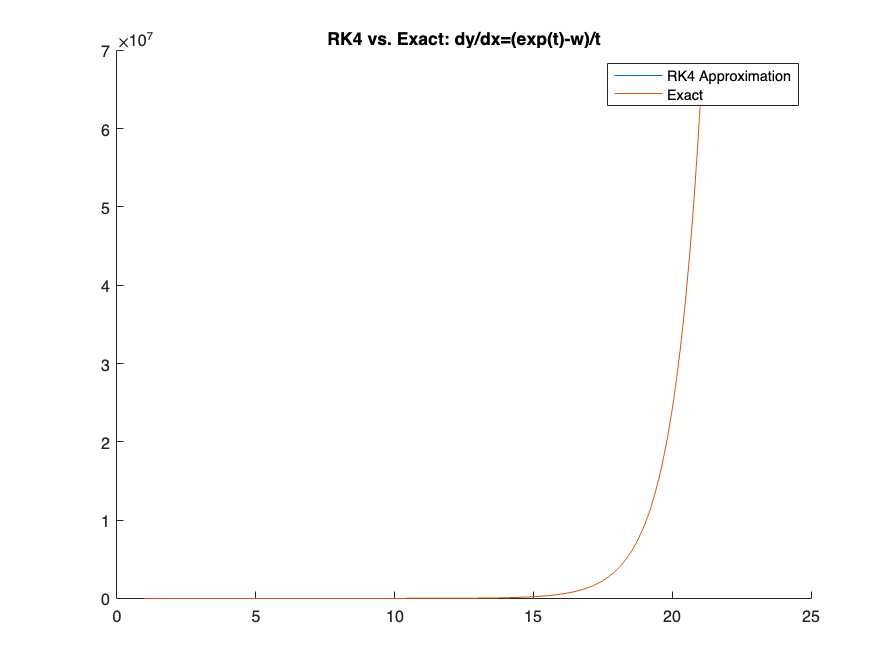

% Compare rk4 approximation to actual values
hold on
title("RK4 vs. Exact: dy/dx=(exp(t)-w)/t");
plot(ti, rk4_wi);
plot(ti, exact_wi);
legend("RK4 Approximation", "Exact");

function [ti, wi] = rk4(N, h, a, alpha, df)
    % Inputs:
    %   N: the number of approximations to make
    %   h: the step size
    %   a: initial independent variable
    %   alpha: the initial value of f at a with D dimensions
    %   df: a differential equation in terms of t and w
    % Outputs:
    %   ti: N+1 values of t that are approximated (including a)
    %   wi: N+1 D-dimensional approximations
    t = a; 
    w = alpha;
    alpha_dim = size(alpha);

    ti = zeros(N+1, 1);
    ti(1) = t;
    wi = zeros(N+1, alpha_dim(1));
    wi(1) = w;

    for i=1:N
        K1 = h .* df(t, w); % slope at beginning of interval
        K2 = h .* df(t + h/2, w + K1/2); % slope at midpoint using K1
        K3 = h .* df(t + h/2, w + K2/2); % slope at midpoint using K3
        K4 = h .* df(t + h, w + K3); % slope at endpoint

        w = w + (K1 + 2*K2 + 2*K3 + K4) / 6; % weighted average of slopes
        t = a + i * h; % t-value approximated by above w

        wi(i+1) = w;
        ti(i+1) = t;
    end
end